# Equivalent Circuit Model

## Load data set

jsonstruct = parseBattmoJson('exampleECM.json');
inputparams = EquivalentCircuitModelInputParams(jsonstruct);

## Setup model

model = EquivalentCircuitModel(inputparams);

## run Simulation

[t, U, I] = model.solve();

## Plotting

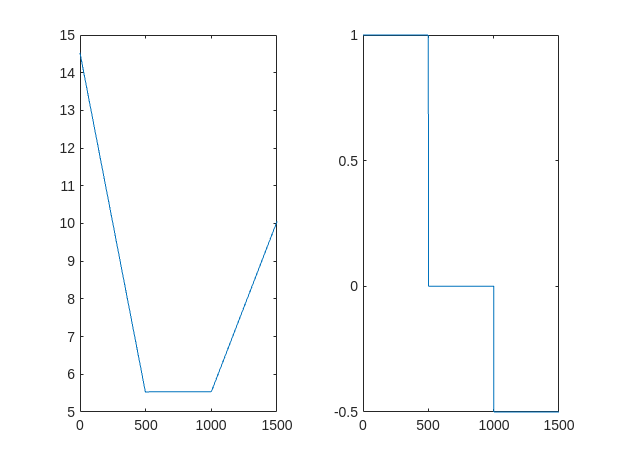

tiledlayout(1, 2);
nexttile
plot(t, U)
nexttile
plot(t, I)